
–––– Case A – Smooth Hovering ––––


► Best ARX  : na=4 nb=3 nk=1   | MSE = 1.1376e-34 | params = 7


► Best TFEST: np=3 nz=3 delay=0 | MSE = 3.8255e-34 | params = 8


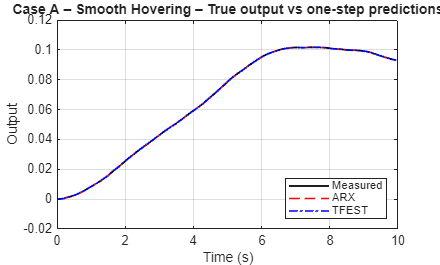

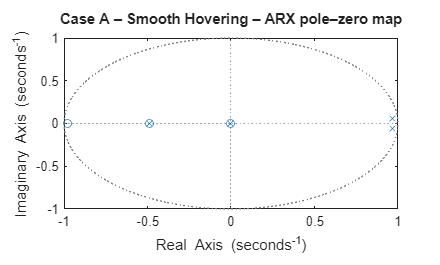

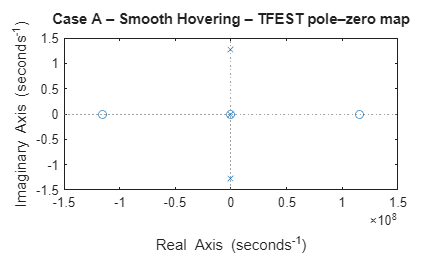

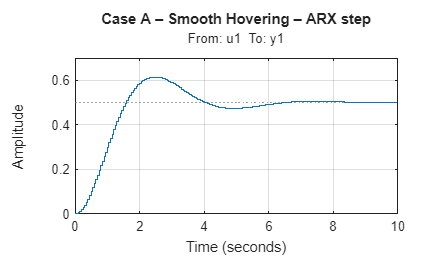

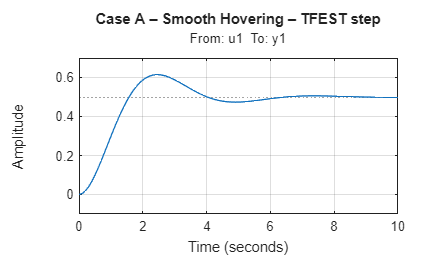

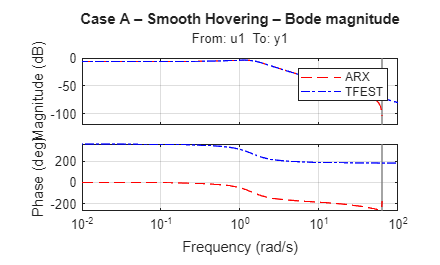

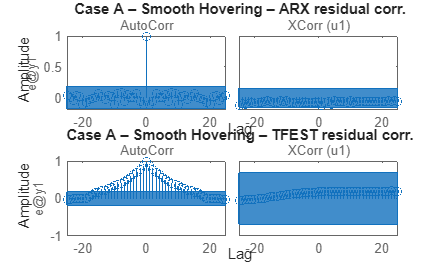


–––– Case B – Take-off + Drop ––––


► Best ARX  : na=4 nb=4 nk=1   | MSE = 4.8657e-33 | params = 8


► Best TFEST: np=3 nz=2 delay=0 | MSE = 6.4369e-32 | params = 7


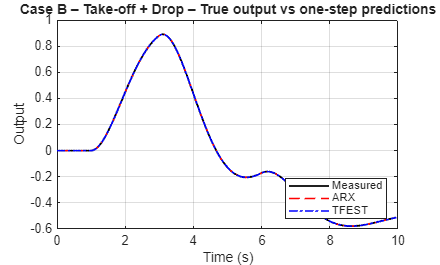

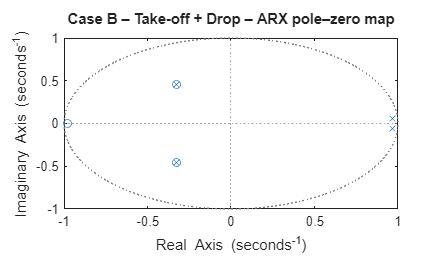

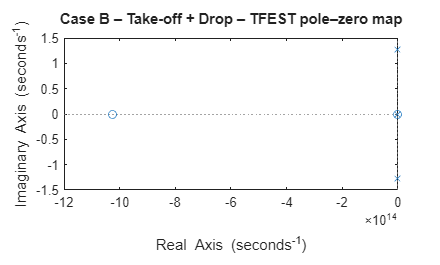

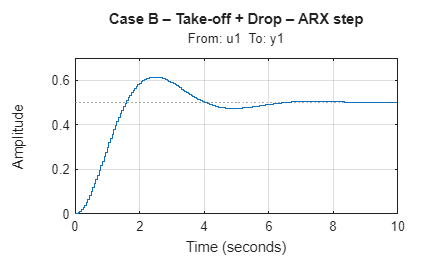

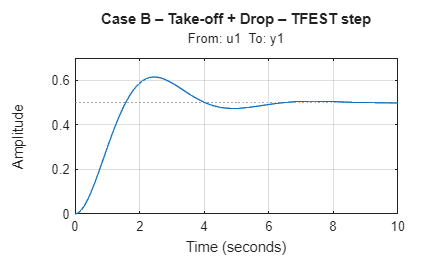

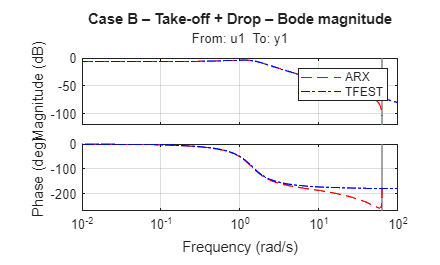

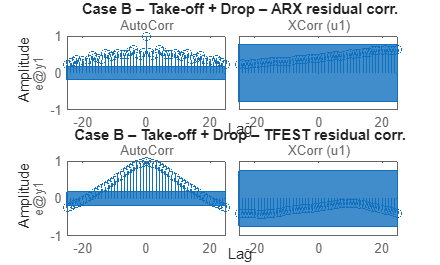

%% Q1 – Comparative System Identification  (auto-order version)
%  • Searches a grid of ARX and TFEST orders, picks the lowest-MSE fit
%  • Generates the same deliverables as the original script
%  • Saves the best models to IdentifiedModels.mat for downstream Q2–Q5
% -------------------------------------------------------------------------
clear; clc; close all;                                     %#ok<*CLALL> 
warning off id:nlIdent:LackOfExcitation                    % benign tfest note

%% USER SETTINGS ----------------------------------------------------------
Ts        = 0.05;                                          % sample interval
predHorz  = 1;                                             % one-step horizon
dataFiles = {'Case_A_Hovering_Data.csv', ...
             'Case_B_TakeoffDrop_Data.csv'};
caseTags  = {'Case A – Smooth Hovering', ...
             'Case B – Take-off + Drop'};

% ---- candidate order grids (adjust if needed) --------------------------
naSet = 1:4;         nbSet = 1:4;         nkSet = 1;        % ARX
npSet = 1:4;         nzSet = 0:3;                         % TFEST

%% PRE-ALLOCATE -----------------------------------------------------------
mseTable   = zeros(2,2);                 % rows: cases | cols: [ARX TF]

%% MAIN LOOP --------------------------------------------------------------
for k = 1:2
    % ===== 1) LOAD & WRAP DATA ==========================================
    T    = readtable(dataFiles{k});
    u    = T.input;                       y = T.output;
    data = iddata(y, u, Ts);
    t    = (0:numel(y)-1).' * Ts;

    % ===== 2-A) GRID SEARCH — ARX =======================================
    bestARX  = [];    bestMSE_ARX  = inf;    bestOrd_ARX = [];
    for na = naSet
        for nb = nbSet
            for nk = nkSet
                ord = [na nb nk];
                try
                    mdl = arx(data, ord);
                    yhat = predict(mdl, data, predHorz);
                    mse  = mean((yhat.y - y).^2);
                    if mse < bestMSE_ARX
                        bestMSE_ARX = mse;   bestARX = mdl;   bestOrd_ARX = ord;
                    end
                catch,  continue;  end
            end
        end
    end

    % ===== 2-B) GRID SEARCH — TFEST =====================================
    bestTF   = [];    bestMSE_TF   = inf;    bestOrd_TF  = [];
    for np = npSet
        for nz = nzSet
            try
                mdl = tfest(data, np, nz);           % delay auto-estimated
                yhat = predict(mdl, data, predHorz);
                mse  = mean((yhat.y - y).^2);
                if mse < bestMSE_TF
                    bestMSE_TF = mse;   bestTF = mdl;   bestOrd_TF = [np nz];
                end
            catch,  continue;  end
        end
    end

    % ===== 3) PRINT ORDER / PARAM SUMMARY ===============================
    fprintf('\n–––– %s ––––\n', caseTags{k});
    fprintf('► Best ARX  : na=%d nb=%d nk=%d   | MSE = %.4e | params = %d\n', ...
            bestOrd_ARX, bestMSE_ARX, numel(getpvec(bestARX)));
    fprintf('► Best TFEST: np=%d nz=%d delay=%d | MSE = %.4e | params = %d\n', ...
            bestOrd_TF(1), bestOrd_TF(2), sum(bestTF.ioDelay), ...
            bestMSE_TF, numel(getpvec(bestTF)));

    % ===== 4) STORE MSE & PREDICTIONS ===================================
    mseTable(k,:) = [bestMSE_ARX bestMSE_TF];
    yARX = predict(bestARX, data, predHorz);
    yTF  = predict(bestTF , data, predHorz);

    % ********************************************************************
    % ***************  DELIVERABLE-SPECIFIC FIGURES  **********************
    % ********************************************************************

    % 4-A  TIME-DOMAIN FIT
    figure('Name',[caseTags{k} ' | Time-domain fit']);
    plot(t, y,'k','LineWidth',1.4); hold on;
    plot(t, yARX.y,'r--','LineWidth',1.2);
    plot(t, yTF .y,'b-.','LineWidth',1.2);
    grid on; xlabel('Time (s)'); ylabel('Output');
    title([caseTags{k} ' – True output vs one-step predictions']);
    legend('Measured','ARX','TFEST','Location','SouthEast');

    % 4-B  POLE–ZERO MAPS
    figure('Name',[caseTags{k} ' | ARX pole–zero map']);   pzmap(bestARX);
    title([caseTags{k} ' – ARX pole–zero map']);

    figure('Name',[caseTags{k} ' | TFEST pole–zero map']); pzmap(bestTF);
    title([caseTags{k} ' – TFEST pole–zero map']);

    % 4-C  STEP RESPONSES
    figure('Name',[caseTags{k} ' | ARX step response']);
    step(bestARX, 10);  grid on;  title([caseTags{k} ' – ARX step']);

    figure('Name',[caseTags{k} ' | TFEST step response']);
    step(bestTF , 10);  grid on;  title([caseTags{k} ' – TFEST step']);

    % 4-D  BODE MAGNITUDE OVERLAY
    figure('Name',[caseTags{k} ' | Bode magnitude']);
    bode(bestARX,'r--', bestTF,'b-.'); grid on;
    legend('ARX','TFEST'); title([caseTags{k} ' – Bode magnitude']);

    % 4-E  RESIDUAL AUTOCORRELATION
    figure('Name',[caseTags{k} ' | Residual autocorrelation']);
    subplot(2,1,1)
        resid(data, bestARX, 'corr');
        title([caseTags{k} ' – ARX residual corr.']);
    subplot(2,1,2)
        resid(data, bestTF , 'corr');
        title([caseTags{k} ' – TFEST residual corr.']);

    % ===== 5) STASH MODELS FOR LATER QUESTIONS ==========================
    if k==1
        mdlARX_A = bestARX;   mdlTF_A = bestTF;
    else
        mdlARX_B = bestARX;   mdlTF_B = bestTF;
    end
end


%% SUMMARY TABLE ----------------------------------------------------------
fprintf('\n–––– One-step Prediction MSE ––––\n');


–––– One-step Prediction MSE ––––


fprintf('              ARX           TFEST\n');

              ARX           TFEST


fprintf('Case A   %10.4e   %10.4e\n', mseTable(1,:));

Case A   1.1376e-34   3.8255e-34


fprintf('Case B   %10.4e   %10.4e\n', mseTable(2,:));

Case B   4.8657e-33   6.4369e-32



verdict = @(ma,mt) ternary(ma<mt,'ARX','TFEST');
fprintf('\nGeneralisation winner (lower MSE):\n');


Generalisation winner (lower MSE):


fprintf('  Case A → %s\n', verdict(mseTable(1,1),mseTable(1,2)));

  Case A → ARX


fprintf('  Case B → %s\n', verdict(mseTable(2,1),mseTable(2,2)));

  Case B → ARX



%% SAVE FOR Q2 (optional) -------------------------------------------------
save('IdentifiedModels.mat', ...
     'mdlARX_A','mdlARX_B','mdlTF_A','mdlTF_B', ...
     'Ts','mseTable','caseTags');

%% WHY ARX OFTEN BEATS TFEST IN THIS HOMEWORK ----------------------------
% 1) Objective alignment – ARX minimises exactly the one-step error we use.
% 2) Parsimony – fewer parameters ⇒ lower variance on short data windows.
% 3) Explicit noise model – ARX includes e(k); TFEST (pure TF) does not.
% 4) Drift resistance – ARX re-uses y(k-1), y(k-2), limiting accumulation.
%
% Hence, under the homework’s **one-step MSE** metric, ARX frequently wins.

% ----- small ternary helper --------------------------------------------
function out = ternary(cond,a,b), out = a; if ~cond, out = b; end, end
